# Final Exam Part 2

clear;close;clc;

## Part 2:

sf = 25.3/8.2 % for refrence only not used in the program

sf = 3.0854



a = 1097.09 %ft/s

a = 1.0971e+03

M = .9

M = 0.9000

rho = .00204

rho = 0.0020



Weight = 11700 %lbs

Weight = 11700

alpha = deg2rad(.5)

alpha = 0.0087

beta = deg2rad(2)

beta = 0.0349


xbar_planform = .25

xbar_planform = 0.2500

xbar_cg = .6

xbar_cg = 0.6000

Delta_xbar_munk = -.08

Delta_xbar_munk = -0.0800


C_M_ac = -.08

C_M_ac = -0.0800


% Main Wing

ct = 2.4683 %ft

ct = 2.4683

cr = 10.1817

cr = 10.1817

b = 25.3

b = 25.3000

c_bar = 7.4

c_bar = 7.4000

lambda = ct/cr

lambda = 0.2424

S = 170

S = 170

Lambda_LE = deg2rad(30)

Lambda_LE = 0.5236

A = b^2/S

A = 3.7652

e = .9

e = 0.9000

C_L_0_wf = .12

C_L_0_wf = 0.1200

C_L_alpha_wf = 3.1

C_L_alpha_wf = 3.1000

C_y_beta_wf = -.23

C_y_beta_wf = -0.2300

C_l_beta_wf = -.016

C_l_beta_wf = -0.0160

C_n_beta_wf = .2

C_n_beta_wf = 0.2000

C_l_delta_a = .013

C_l_delta_a = 0.0130

C_n_delta_a = -.01

C_n_delta_a = -0.0100

xbar_ac_wf = .25

xbar_ac_wf = 0.2500



% Horizontal Tail

ct_h = 1.8512 %ft

ct_h = 1.8512

cr_h = 6.1707

cr_h = 6.1707

b_h = 13.8841

b_h = 13.8841

c_bar_h = 4.6280

c_bar_h = 4.6280

lambda_h = ct_h/cr_h

lambda_h = 0.3000

S_h = b_h/2 * cr_h * (1+lambda_h)

S_h = 55.6884

A_h = b_h^2/S_h

A_h = 3.4615

%x_LE_h = 13.2671
%x_ac_h = x_LE_h - xbar_planform * c_bar + xbar_planform * c_bar_h
x_ac_h = 12.3415

x_ac_h = 12.3415

Lambda_LE_h = deg2rad(30)

Lambda_LE_h = 0.5236

epsilon_0 = deg2rad(.4)

epsilon_0 = 0.0070

eta_h = .9

eta_h = 0.9000

C_L_alpha_h = 5.82

C_L_alpha_h = 5.8200

C_y_beta_h = -.04

C_y_beta_h = -0.0400

C_l_beta_h = -.009

C_l_beta_h = -0.0090

C_n_beta_h = .03

C_n_beta_h = 0.0300

downwashGradient = .3907

downwashGradient = 0.3907




% Verticle Tail

ct_v = 2.4683 %ft

ct_v = 2.4683

cr_v = 9.5646

cr_v = 9.5646

b_v = 6.7878

b_v = 6.7878

c_bar_v = 6.7878

c_bar_v = 6.7878

lambda_v = ct_v/cr_v

lambda_v = 0.2581

S_v = b_v/2 * cr_v * (1+lambda_v)

S_v = 40.8385

A_v = b_v^2/S_v

A_v = 1.1282

%x_LE_h = 13.2671
%x_ac_h = x_LE_h - xbar_planform * c_bar + xbar_planform * c_bar_h
Lambda_LE_v = deg2rad(38)

Lambda_LE_v = 0.6632

x_v_s = 10.7988

x_v_s = 10.7988

z_v_s = 4.6280

z_v_s = 4.6280

C_L_alpha_v = 1.73

C_L_alpha_v = 1.7300

eta_v = .96

eta_v = 0.9600

sidewashGradient = .3

sidewashGradient = 0.3000

tau_delta_r = .4

tau_delta_r = 0.4000



% question 1
fprintf("question: 1")

question: 1


xbar_ac_h = x_ac_h/c_bar

xbar_ac_h = 1.6678


C_L_0 = C_L_0_wf + C_l_beta_h * (-epsilon_0)

C_L_0 = 0.1201

C_L_alpha = C_L_alpha_wf + eta_h * S_h/S * C_L_alpha_h * (1 - downwashGradient)

C_L_alpha = 4.1455

C_L_ih = eta_h * S_h/S * C_L_alpha_h

C_L_ih = 1.7159



% question 2
fprintf("question: 2")

question: 2


%drag
C_Dbar_0 = 0.0162

C_Dbar_0 = 0.0162

C_L = C_L_0 + C_L_alpha * alpha

C_L = 0.1562

C_D = C_Dbar_0 + (C_L^2) / (pi*A*e)

C_D = 0.0185


%thrust required
v = M*a

v = 987.3810

qbar = (1/2) * rho * v^2

qbar = 994.4197


thrust = qbar * S * (C_D*cos(alpha) - C_L*sin(alpha))

thrust = 2.8956e+03

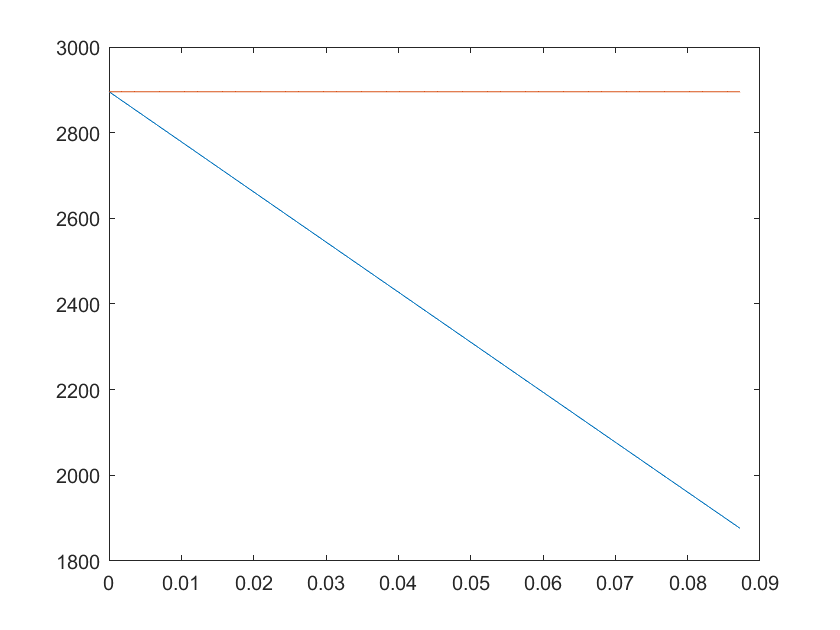


theta = deg2rad([0:.1:5]);
for i = 1:length(theta)
    thrust_w(i) = qbar * S * (C_D*cos(alpha) - C_L*sin(alpha)) - Weight*sin(theta(i));
end
plot(theta,thrust_w); hold on
plot(theta,repelem(thrust,length(theta)))



% question 3
fprintf("question: 3")

question: 3


C_M_0 = C_M_ac + C_L_0_wf * (xbar_cg - (xbar_ac_wf + Delta_xbar_munk)) + eta_h * S_h/S * C_L_alpha_h * (epsilon_0) * (xbar_cg - xbar_ac_h)

C_M_0 = -0.0412

C_M_alpha = C_L_alpha_wf * (xbar_cg - (xbar_ac_wf + Delta_xbar_munk)) + eta_h * S_h/S * C_L_alpha_h * (1-downwashGradient) * (xbar_cg - xbar_ac_h)

C_M_alpha = 0.2167

C_M_ih =  eta_h * S_h/S * C_L_alpha_h * (xbar_cg - xbar_ac_h)

C_M_ih = -1.8321



% question 4
fprintf("question: 4")

question: 4


xbar_ac_a = (C_L_alpha_wf * (xbar_ac_wf + Delta_xbar_munk)+ + eta_h * S_h/S * C_L_alpha_h * (1 - downwashGradient) * xbar_ac_h) / (C_L_alpha_wf + eta_h * S_h/S * C_L_alpha_h * (1 - downwashGradient))

xbar_ac_a = 0.5477


StaticMargin = -(xbar_cg - xbar_ac_a)

StaticMargin = -0.0523

-C_M_alpha/C_L_alpha

ans = -0.0523



% question 5
fprintf("question: 5")

question: 5


xbar_ac_wf = .4

xbar_ac_wf = 0.4000

xbar_ac_h = 12.0329/c_bar

xbar_ac_h = 1.6261


C_M_0 = C_M_ac + C_L_0_wf * (xbar_cg - (xbar_ac_wf + Delta_xbar_munk)) + eta_h * S_h/S * C_L_alpha_h * (epsilon_0) * (xbar_cg - xbar_ac_h)

C_M_0 = -0.0587

C_M_alpha = C_L_alpha_wf * (xbar_cg - (xbar_ac_wf + Delta_xbar_munk)) + eta_h * S_h/S * C_L_alpha_h * (1-downwashGradient) * (xbar_cg - xbar_ac_h)

C_M_alpha = -0.2047

C_M_ih =  eta_h * S_h/S * C_L_alpha_h * (xbar_cg - xbar_ac_h)

C_M_ih = -1.7606

-C_M_alpha/C_L_alpha

ans = 0.0494



% question 7
fprintf("question: 7")

question: 7


%shifted AC
ih = (-C_M_0 - C_M_alpha) / C_M_ih

ih = -0.1496


%original AC
xbar_ac_wf = .25

xbar_ac_wf = 0.2500

xbar_ac_h = x_ac_h/c_bar % the original position

xbar_ac_h = 1.6678

C_M_0 = C_M_ac + C_L_0_wf * (xbar_cg - (xbar_ac_wf + Delta_xbar_munk)) + eta_h * S_h/S * C_L_alpha_h * (epsilon_0) * (xbar_cg - xbar_ac_h)

C_M_0 = -0.0412

C_M_alpha = C_L_alpha_wf * (xbar_cg - (xbar_ac_wf + Delta_xbar_munk)) + eta_h * S_h/S * C_L_alpha_h * (1-downwashGradient) * (xbar_cg - xbar_ac_h)

C_M_alpha = 0.2167

C_M_ih =  eta_h * S_h/S * C_L_alpha_h * (xbar_cg - xbar_ac_h)

C_M_ih = -1.8321

-C_M_alpha/C_L_alpha

ans = -0.0523


ih = (-C_M_0 - C_M_alpha) / C_M_ih

ih = 0.0958



% question 8
fprintf("question: 8")

question: 8


C_y_beta = C_y_beta_wf + eta_h * S_h/S * C_y_beta_h + eta_v * S_v/S * (-C_L_alpha_v * (1-sidewashGradient))

C_y_beta = -0.5211

C_l_beta = C_l_beta_wf + eta_h * S_h/S * b_h/b * C_l_beta_h + eta_v * S_v/S * z_v_s/b * (-C_L_alpha_v * (1-sidewashGradient))

C_l_beta = -0.0685

C_n_beta = C_n_beta_wf + eta_h * S_h/S * b_h/b * C_n_beta_h + eta_v * S_v/S * x_v_s/b * (C_L_alpha_v * (1-sidewashGradient))

C_n_beta = 0.3241

C_y_delta_r = eta_v * S_v/S * C_L_alpha_v * tau_delta_r

C_y_delta_r = 0.1596

C_l_delta_r = eta_v * S_v/S * C_L_alpha_v * z_v_s/b * tau_delta_r

C_l_delta_r = 0.0292

C_n_delta_r = eta_v * S_v/S * C_L_alpha_v * x_v_s/b * tau_delta_r

C_n_delta_r = 0.0681


C_y_beta_v = eta_v * S_v/S * (-C_L_alpha_v * (1-sidewashGradient))

C_y_beta_v = -0.2793

C_l_beta_v = eta_v * S_v/S * z_v_s/b * (-C_L_alpha_v * (1-sidewashGradient))

C_l_beta_v = -0.0511

C_n_beta_v = eta_v * S_v/S * x_v_s/b * (C_L_alpha_v * (1-sidewashGradient))

C_n_beta_v = 0.1192



% question 9
fprintf("question: 9")

question: 9


delta_r = (-C_n_beta*beta) / C_n_delta_r

delta_r = -0.1661

rad2deg(delta_r)

ans = -9.5148


% question 10
fprintf("question: 10")

question: 10


delta_a = (-C_l_beta*beta) / C_l_delta_a

delta_a = 0.1840

rad2deg(delta_a)

ans = 10.5451


% question 11
fprintf("question: 11")

question: 11


delta_r = (-C_l_beta*beta) / C_l_delta_r

delta_r = 0.0820

rad2deg(delta_r)

ans = 4.6959


% question 12
fprintf("question: 12")

question: 12


delta_a = (-C_n_beta*beta) / C_n_delta_a

delta_a = 1.1312

rad2deg(delta_a)

ans = 64.8115


% question 13
fprintf("question: 13")

question: 13


delta_r = (-C_n_beta*beta) / C_n_delta_r

delta_r = -0.1661

rad2deg(delta_r)

ans = -9.5148